%I wish i was levar burton
%dont rainbow reed me friend

%u1
syms z;


%u2
X1=2*(z^-1)+4*(z^-2)+5*(z^-3)+3*(z^-4)+2*(z^-5)

$$X1 = \frac{2}{z}+\frac{4}{z^{2}}+\frac{5}{z^{3}}+\frac{3}{z^{4}}+\frac{2}{z^{5}}$$

%u3
iztrans(X1)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$

%i spatial domänids
%svaret ska tolkas som en sekvens av pulser, hur x1[n] ser ut

%u4
X1p=z^-5*(2*(z^4)+4*(z^3)+5*(z^2)+3*(z^1)+2)

$$X1p = \frac{2\,z^{4}+4\,z^{3}+5\,z^{2}+3\,z+2}{z^{5}}$$

iztrans(X1p)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$

%u5 
num = [2 4 5 3 2];
den = [1 0 0 0 0 0];

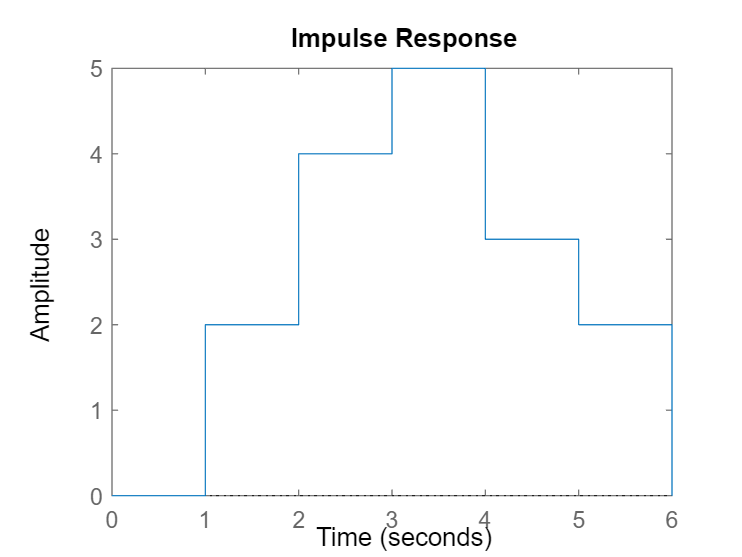

%u6
dimpulse(num,den,7)

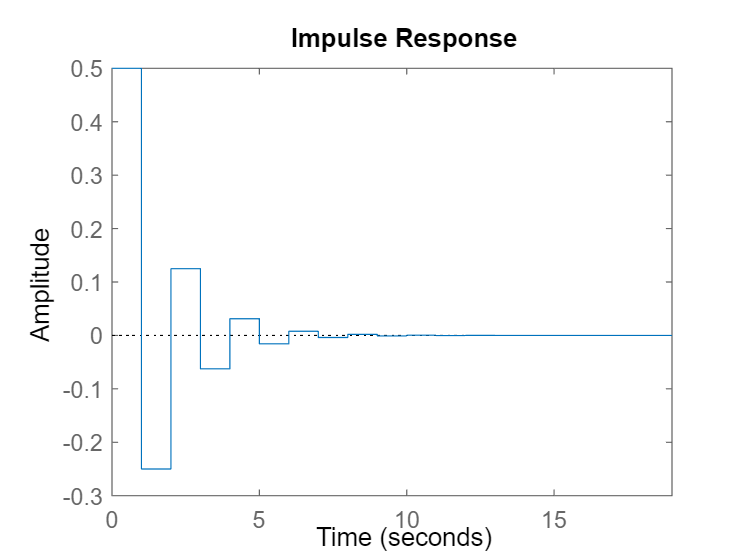

%u7
% förenklas till z /(2z+1)
num = [1 0];
den = [2 1];
dimpulse(num,den,20)

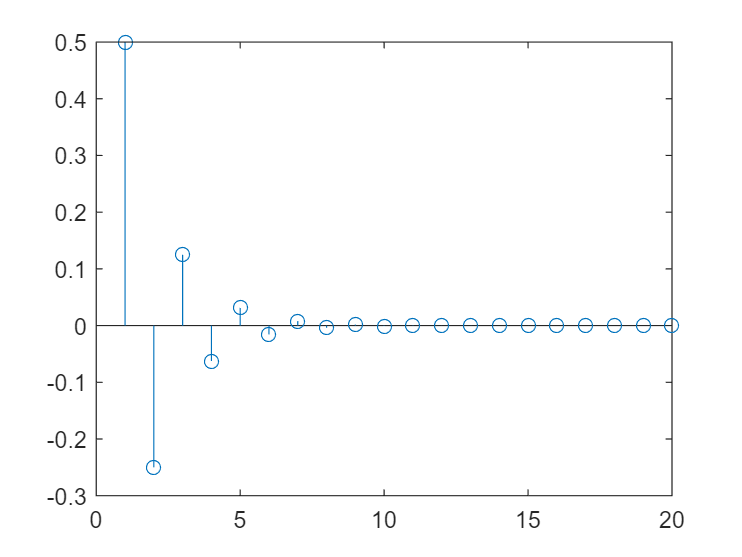

stem(dimpulse(num,den,20))

%u8
X2=z*(2*z+1)^(-1)

$$X2 = \frac{z}{2\,z+1}$$

iztrans(X2)

$$ans = \frac{{\left(-\frac{1}{2}\right)}^{n}}{2}$$

%u9
%X2=z*(2*z+1)^(-1)
%iztrans(X2)

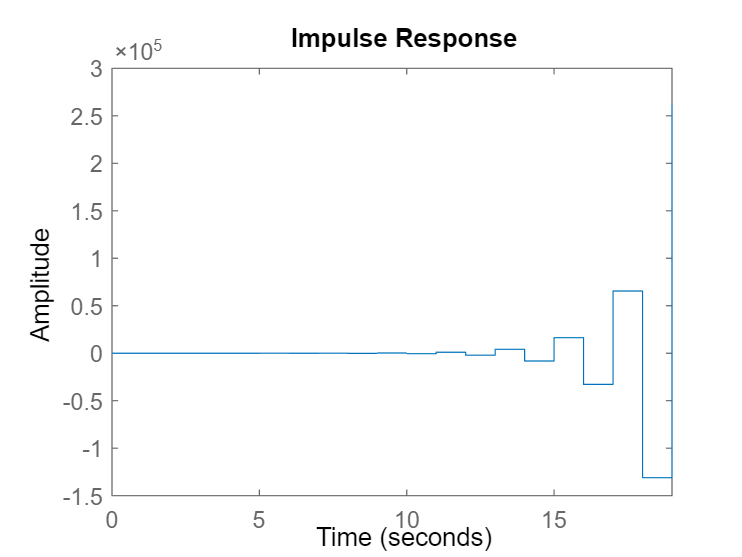

%u10
clf
dimpulse([0 1], [1 2], 20)  % z = -2

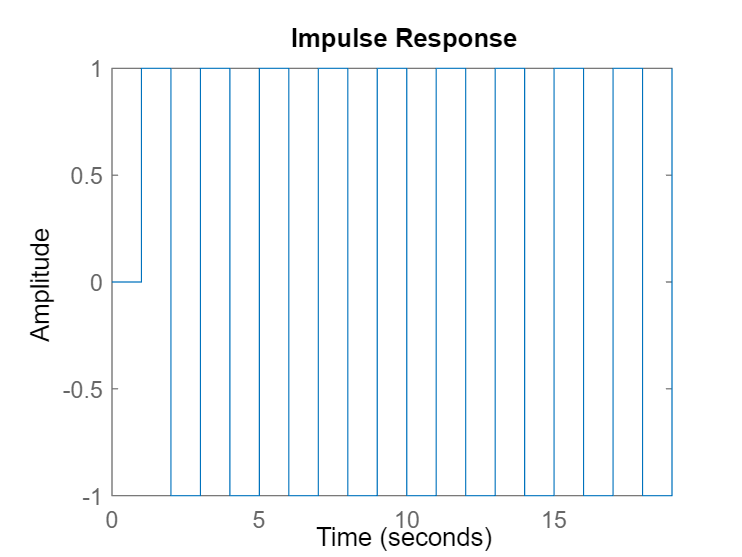

dimpulse([0 1], [1 1], 20)  % z = -1

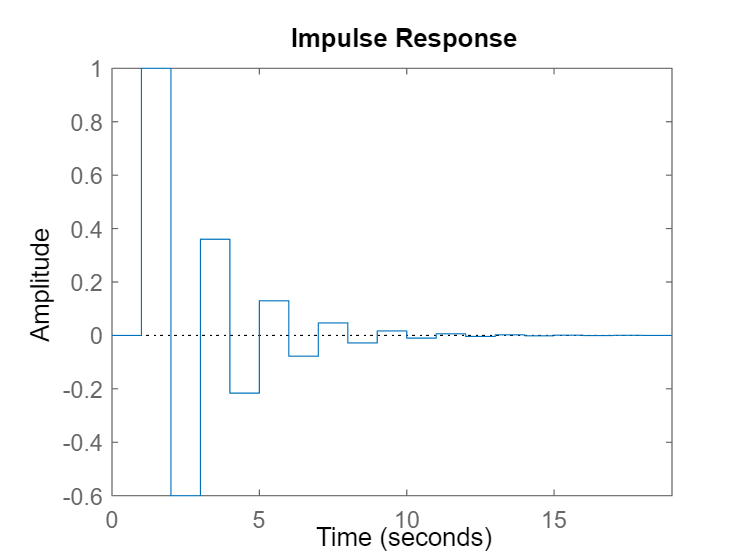

dimpulse([0 1], [1 0.6], 20) % z = -0.6

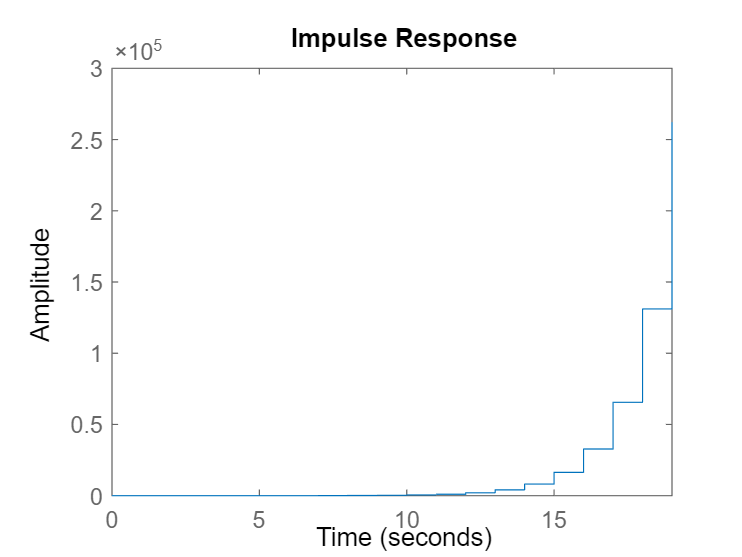

dimpulse([0 1], [1 -2], 20) % z = 2

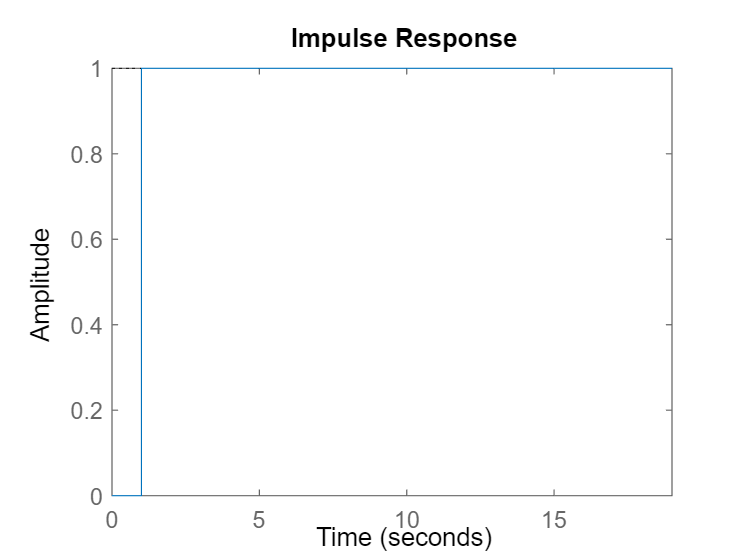

dimpulse([0 1], [1 -1], 20) % z = 1

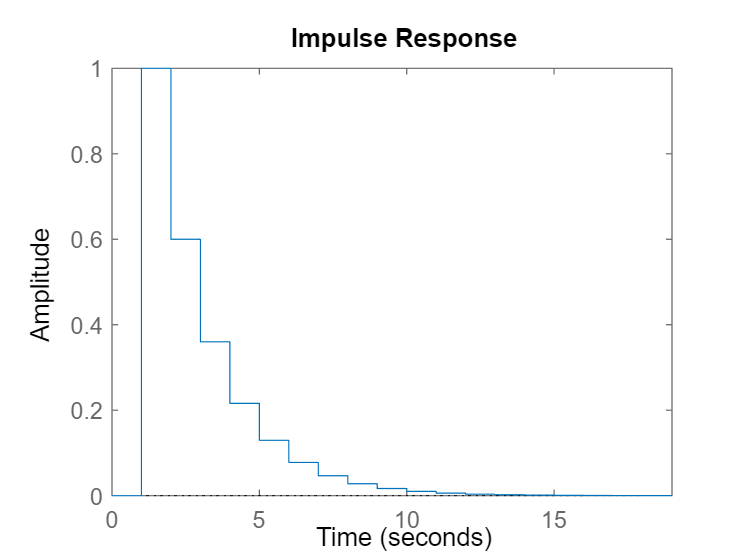

dimpulse([0 1], [1 -0.6], 20)  % z = 0.6

% |a| då a är utanför cirkeln blir det stigande värden  
% a = -1 leder till massa olika värden 
% a = 1 blir det 1 värder vast konstant stort
% |a| då a är innanför cirkeln blir det avtagande värden
% poler är viktiga

%u11 FFFFFFFFFFFFFFFFRURIKC
X7 = 1/((z-(1/sqrt(2)+j*1/sqrt(2))) * (z-(1/sqrt(2)-j*1/sqrt(2))))

$$X7 = -\frac{1}{\left(\frac{\sqrt{2}\,j}{2}-z+\frac{\sqrt{2}}{2}\right)\,\left(z+\frac{\sqrt{2}\,j}{2}-\frac{\sqrt{2}}{2}\right)}$$

iztrans(X7)

$$ans = \begin{array}{l} \left\{ \begin{array}{cl} -\sqrt{2}\,\left(\frac{\sqrt{2}\,\delta_{n,0}}{4}-\frac{2^{n/2}\,\sqrt{2}}{4}\right)-\frac{\sqrt{2}\,\delta_{n-1,0}}{2} & \text{ if }j=-1\vee j=1\\ \frac{\sqrt{2}\,\left(\frac{{\left(\frac{\sqrt{2}}{2}-\sigma_{3}\right)}^{n}}{\sigma_{1}}-\frac{\delta_{n,0}}{\sigma_{1}}\right)}{j}-\frac{\sqrt{2}\,\left(\frac{\delta_{n,0}}{\sigma_{2}}-\frac{{\left(\sigma_{3}+\frac{\sqrt{2}}{2}\right)}^{n}}{\sigma_{2}}\right)}{j} & \text{ if }j\neq -1\wedge j\neq 1 \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,j-\sqrt{2}\\ \sigma_{2}=\sqrt{2}\,j+\sqrt{2}\\ \sigma_{3}=\frac{\sqrt{2}\,j}{2} \end{array}$$

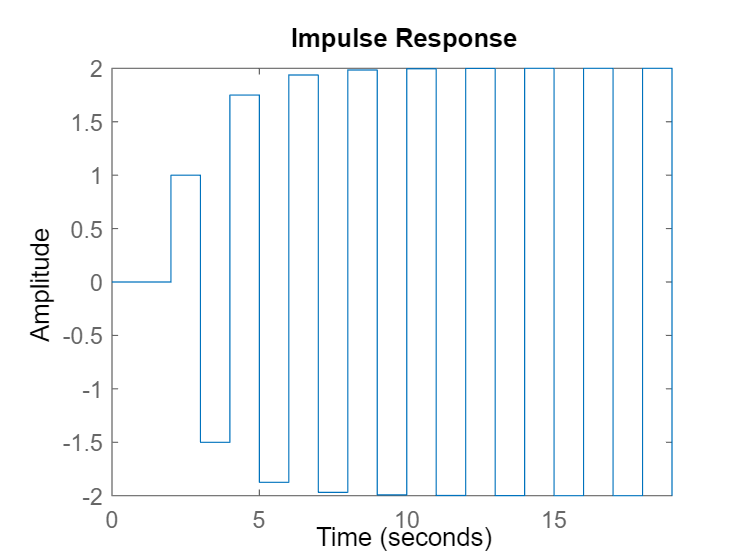

%u12 + u13 FIIFISDIFSDIFISDIF
dimpulse([0 0 1], [1 1.5 0.5], 20)

% 

%u14 + u15
[x, fs] = audioread('mooncradle.wav')

x =          0
    0.0399
    0.0796
    0.1191
    0.1582
    0.1968
    0.2269
    0.2641
    0.3082
    0.3435


fs = 22050

soundsc(x, fs)
% man kan inte titta på datan direkt för den är bakad in i alla värden på x
% amplituderna vid varje tidsinstans

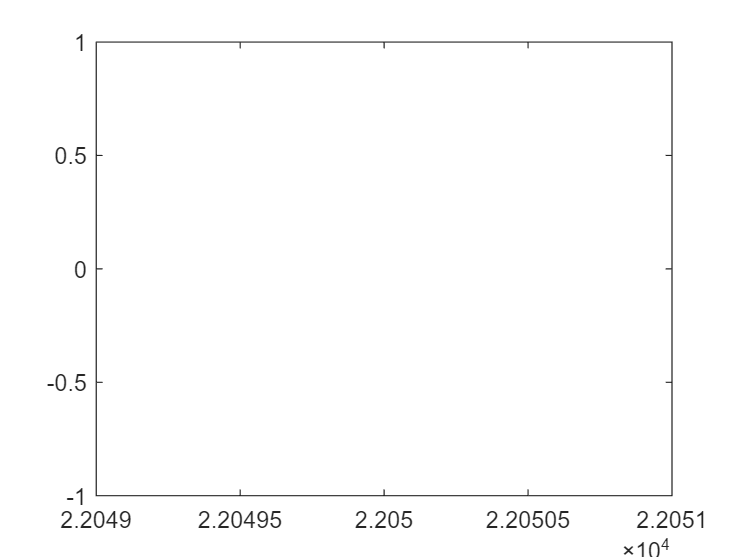

%u16

% z^2 -z*z0 - z*z0inv + z0*z0inv
ohm = 2*pi*200/fs;
z0 = exp(j*ohm)
%
%
%
